clear all;
% Loading workspace variables
run('load_params_estimatedValues.m');

# PID parameters (Bode method)

% Semplified plant
simp_model.P

ans =
 
        77.86
  -----------------
  0.4154 s^2 + 14 s
 
Continuous-time transfer function.



The time-domain specifications on the settling-time and overshoot can be converted into specifications for the loop transfer function by resorting to the following approximate relations:


$$\omega_{gc}\;\approx\;\frac{3}{\delta\,t_{s,5\%}}$$



$$\varphi_m \;=\; \mathrm{atan}\,\frac{2\delta}{\sqrt{\sqrt{1+4\delta^4} - 2\delta^2}}$$


The *damping factor* $\delta$ is related to the overshoot $M_p$ according to the following expression:


$$\delta \;=\; \frac{\log(1/M_p)}{\sqrt{\pi^2 + \log^2(1/M_p)}}$$


%   position controller specs
pctrl.ts = 0.15;                                            %   desired settling time (at 5%)
pctrl.Mp = 0.1;                                             %   desired overshoot

%   get specs for loop tf 
d = log(1/pctrl.Mp) / sqrt(pi^2 + log(1/pctrl.Mp)^2);       %   damping factor
pctrl.wgc = 3/d/pctrl.ts;                                   %   gain crossover freq [rad/s]          
pctrl.phim = 180/pi * atan(2*d/sqrt(sqrt(1+4*d^4)-2*d^2));  %   phase margin [deg]

Let


$$C(s) \;=\; K_P \,+\, \frac{K_I}{s} \,+\, K_D\,s \;=\; K_P \left( 1 \,+\, \frac{1}{T_I s} \,+\, T_D\,s\right)$$


be the controller transfer function. Then, the controller gains $K_P$, $T_D$ and $T_I$ can be obtained as follows:


$$\left\{
\begin{array}{rcl}
K_P & = & \Delta K \, \cos\Delta\varphi \\
T_D & = &\frac{\tan \Delta\varphi + \sqrt{\tan^2 \Delta\varphi + 4/\alpha}}{2\,\omega_{gc}} \\
T_I & = & \alpha T_D
\end{array}
\right.
$$


where


$$ \Delta K = | P(j\omega_{gc}) |^{-1}\,,\quad 
\Delta \varphi = -\pi + \varphi_m - \angle P(j\omega_{gc}) 
$$


and


$$K_D = K_P T_D\,,\quad K_I = K_P / T_I$$


The parameter $\alpha=T_I/T_D$ is selected by the designer.

% Bode Method
[kp, ki, kd] = BodMet(pctrl.wgc,pctrl.phim,simp_model);
kp

kp = 8.3738

ki

ki = 111.2674

kd

kd = 0.1575

% Controller
s = tf('s');
bod_met.controller = kp + ki/s + kd*s/(0.000*s+1); % Controller
bod_met.controller

ans =
 
  0.1575 s^2 + 8.374 s + 111.3
  ----------------------------
               s
 
Continuous-time transfer function.



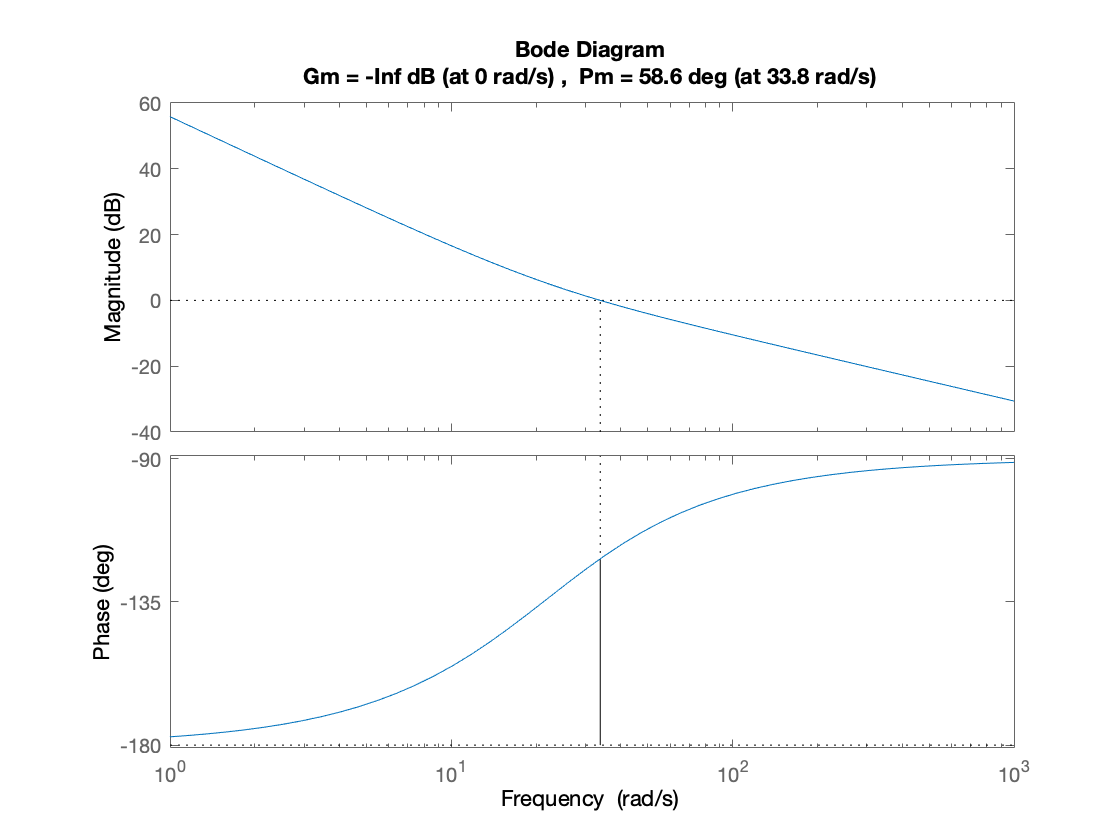

% Verify frequency specs
margin(bod_met.controller*simp_model.P)

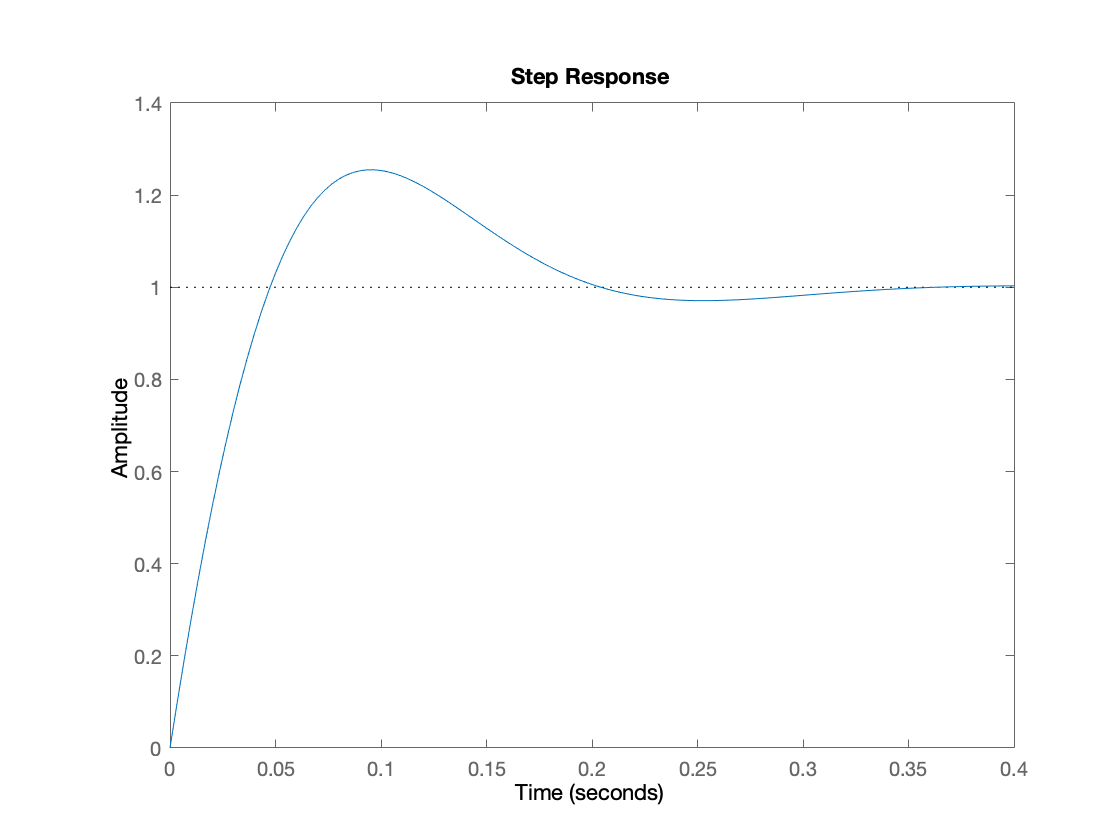

% Closed loop TF
bod_met.W = feedback(bod_met.controller*simp_model.P,1);
% Get tr,ts,mp
charac.tr = stepinfo(bod_met.W).RiseTime;
charac.ts = stepinfo(bod_met.W).SettlingTime;
charac.mp = stepinfo(bod_met.W).Overshoot;
step(bod_met.W)

charac

charac = struct with fields:
    tr: 0.0366
    ts: 0.2927
    mp: 25.5024


# 2.1 Position PID–control improvements

## 1.  Anti-Windup

### 2.1.1

% Loading workspace variables
run('load_params_estimatedValues.m');
AW.K_w = 5/0.15; 
AW.K_w = 40; % Trial & Error

### 2.1.2

#### Simulation results

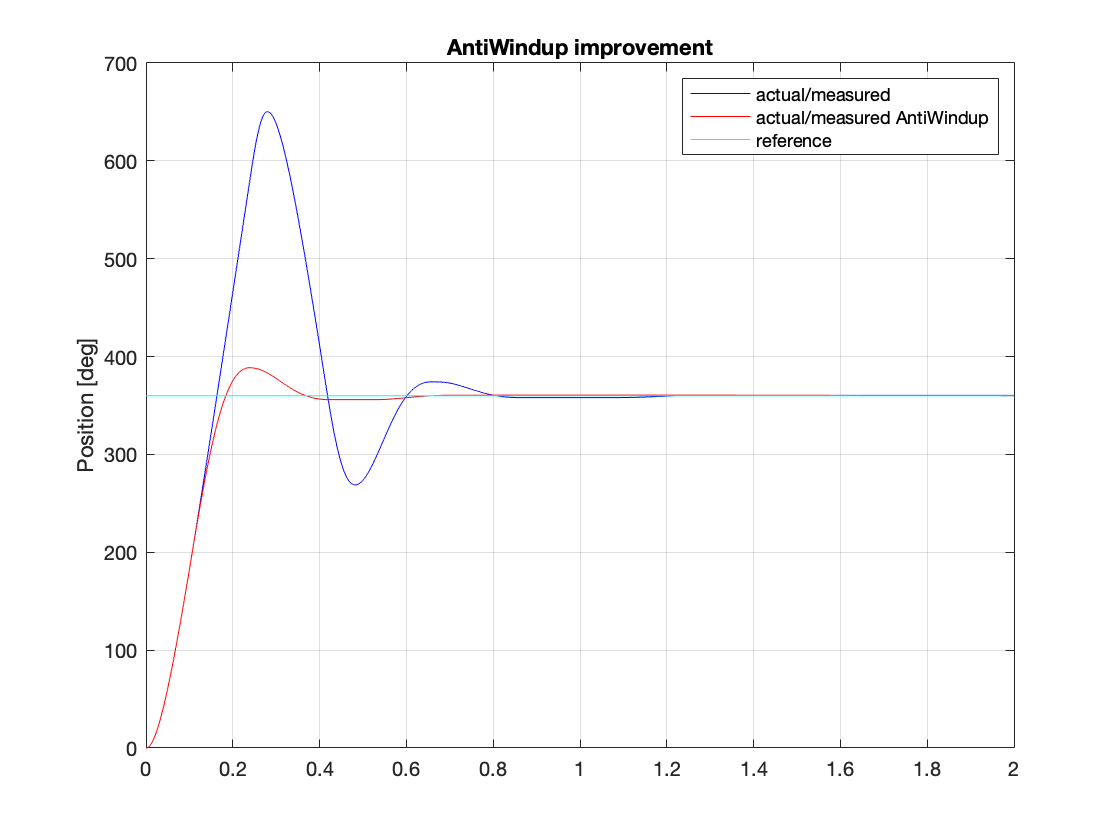

% Open Simulink model
open_system('Simulink/AntiWindup_FF.slx');

% Set parameters
set_param('AntiWindup_FF', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2');
set_param('AntiWindup_FF/Enable Anti-Windup','Value','0');
set_param('AntiWindup_FF/Enable Feed-forward','Value','0');
set_param('AntiWindup_FF/Enable Anti-Windup1','Value','1'); % Anti-Windup ON
set_param('AntiWindup_FF/Enable Feed-forward1','Value','0');

% PID controller AW & FF
set_param('AntiWindup_FF/PID controller_AWFF/proportional','Gain','kp_best');
set_param('AntiWindup_FF/PID controller_AWFF/derivative','Gain','kd_best');
set_param('AntiWindup_FF/PID controller_AWFF/integrative','Gain','ki_best');
set_param('AntiWindup_FF/PID controller_AWFF1/proportional','Gain','kp_best');
set_param('AntiWindup_FF/PID controller_AWFF1/derivative','Gain','kd_best');
set_param('AntiWindup_FF/PID controller_AWFF1/integrative','Gain','ki_best');

% Switch
set_param('AntiWindup_FF/switch','sw','1'); 
set_param('AntiWindup_FF/switch1','sw','1');

% Run simulation
sim('AntiWindup_FF');

% Extract simulation results
AW.t = simres.time; % time vector                        
AW.thl = simres.signals(1).values(:,1); % load position
AW.thl_AW = simres.signals(1).values(:,2); % load position (AW)
AW.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(1);
plot(AW.t, AW.thl, 'b-');
hold on;
plot(AW.t, AW.thl_AW, 'r-');
hold on;
plot(AW.t, AW.thl_Ref, 'c-');
ylabel('Position [deg]');
grid on;
ylim([0,700]);
title('AntiWindup improvement');
legend('actual/measured', 'actual/measured AntiWindup', 'reference');

## 2.  Feed-Forward

### 2.1.3-2.1.4

#### Simulation results

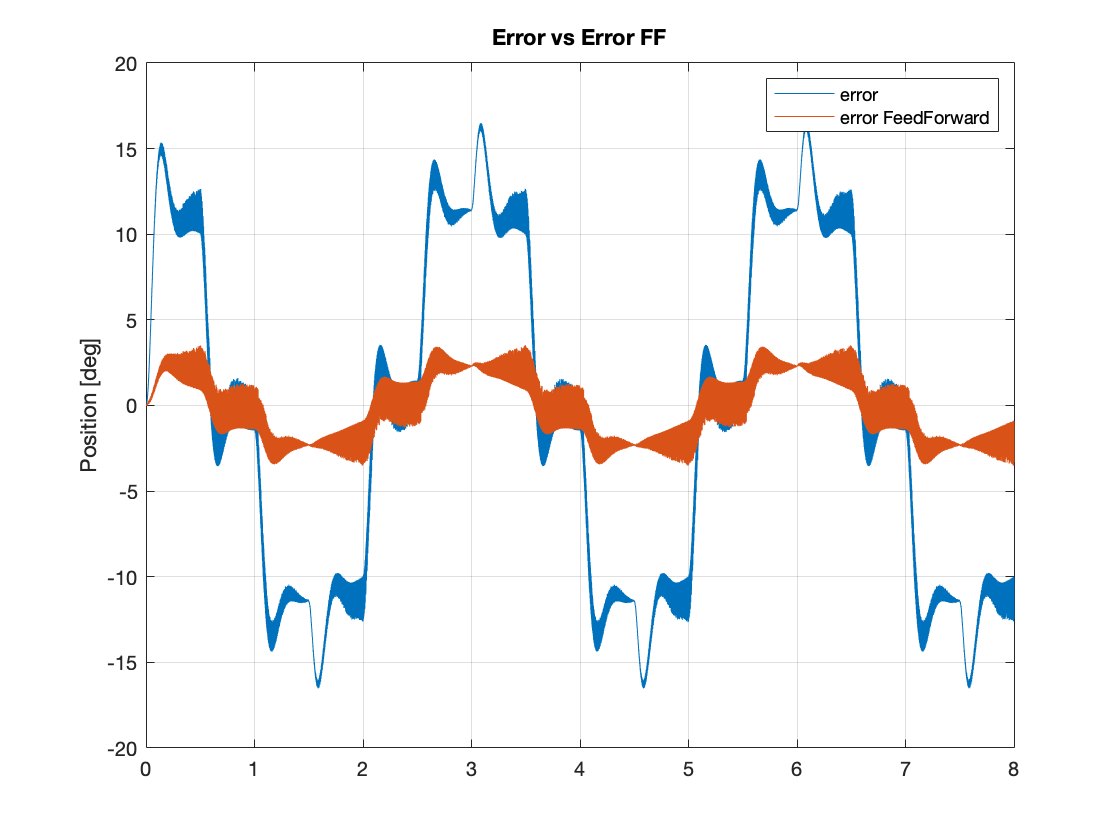

% Set parameters
set_param('AntiWindup_FF', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '8');
set_param('AntiWindup_FF/Enable Anti-Windup','Value','0');
set_param('AntiWindup_FF/Enable Feed-forward','Value','0');
set_param('AntiWindup_FF/Enable Anti-Windup1','Value','0');
set_param('AntiWindup_FF/Enable Feed-forward1','Value','1'); % Feed-Forward ON

% Switch
set_param('AntiWindup_FF/switch','sw','0'); 
set_param('AntiWindup_FF/switch1','sw','0');

% Run simulation
sim('AntiWindup_FF');

% Extract simulation results
FF.err_t = error.time; % time vector                        
FF.err_thl = error.signals(1).values(:,1); % load position
FF.err_thl_FF = error.signals(1).values(:,2); % load position (AW)

% Plot simulation results
figure(2);
plot(FF.err_t, FF.err_thl);
hold on;
plot(FF.err_t, FF.err_thl_FF);
ylabel('Position [deg]');
grid on;
ylim([-20,20]);
title('Error vs Error_ FF');
legend('error', 'error FeedForward');

# 2.2 Position state–space control design

## 1.  $\bf{State-Space\  Nominal \ Control}$

### 2.2.1

% Loading workspace variables
run('load_params_estimatedValues.m');
% State-Space model
state_space.T_m = (simp_model.Req*est_par.J_eq)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.K_m = (drv.dcgain*mot.Kt)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.A = [0 1;0 -1/state_space.T_m];
state_space.B = [0;state_space.K_m/(state_space.T_m*gbox.N)];
state_space.C = [1 0];
state_space.D = 0;

% Nx, Nu
nominal.X = linsolve([state_space.A,state_space.B;state_space.C 0],[0;0;1]);
nominal.N_x = nominal.X(1:2,:);
nominal.N_u = nominal.X(3,:);

% Dominant Pole Approximation
mp = 0.1;
ts = 0.15;
nominal.delta = log(1/mp)/(sqrt(pi*pi + log(1/mp)*log(1/mp)));
nominal.wn = 3/(nominal.delta*ts);
nominal.Tnum = nominal.wn^2;
nominal.Tden = [1 2*nominal.delta*nominal.wn nominal.wn^2];
nominal.T = tf(nominal.Tnum,nominal.Tden); % Dominant closed–loop dynamics approximation

% Pole placement
nominal.p1 = -nominal.delta*nominal.wn + 1i*nominal.wn*sqrt(1-nominal.delta^2);
nominal.p2 = conj(nominal.p1);
nominal.poles = [nominal.p1 nominal.p2];
nominal.K = place(state_space.A,state_space.B,nominal.poles);

### 2.2.2

#### Simulation results 40°

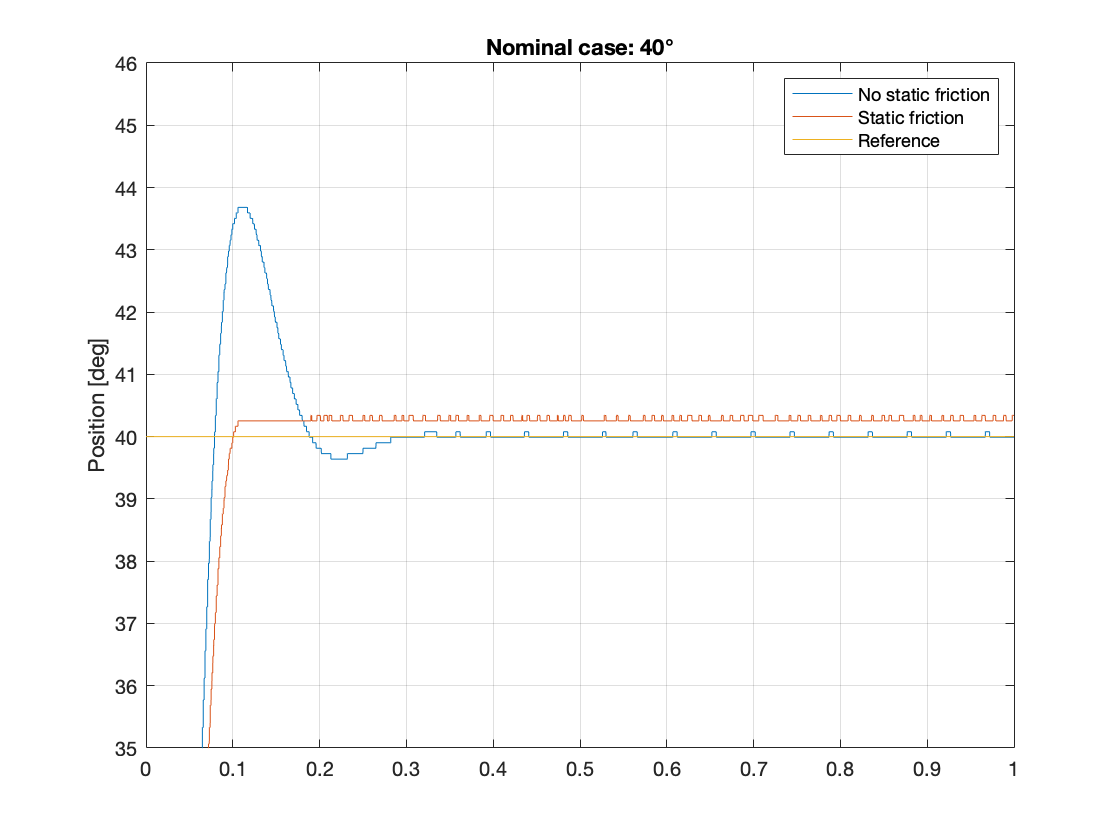

% Open Simulink model
open_system('Simulink/SS_Nominal_Integral.slx');

% Set parameters
set_param('SS_Nominal_Integral', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '1');
% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','40');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','40');
% State-space Controller
set_param('SS_Nominal_Integral/State-space Controller/integral','sw','0'); % Nominal action ON
set_param('SS_Nominal_Integral/State-space Controller1/integral','sw','0'); % Nominal action ON
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','0'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','0'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','nominal.K');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','nominal.K');
set_param('SS_Nominal_Integral/State-space Controller/State feedforward gain','Gain','nominal.N_x');
set_param('SS_Nominal_Integral/State-space Controller1/State feedforward gain','Gain','nominal.N_x');
set_param('SS_Nominal_Integral/State-space Controller/Input feedforward gain','Gain','nominal.N_u');
set_param('SS_Nominal_Integral/State-space Controller1/Input feedforward gain','Gain','nominal.N_u');
% DC motor + gearbox
set_param('SS_Nominal_Integral/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Nominal_Integral/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
nominal.t = simres.time; % time vector                        
nominal.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
nominal.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
nominal.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(3);
plot(nominal.t, nominal.thl_nsf);
hold on;
plot(nominal.t, nominal.thl_sf);
hold on;
plot(nominal.t, nominal.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([35,46]);
title('Nominal case: 40°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation results 70°

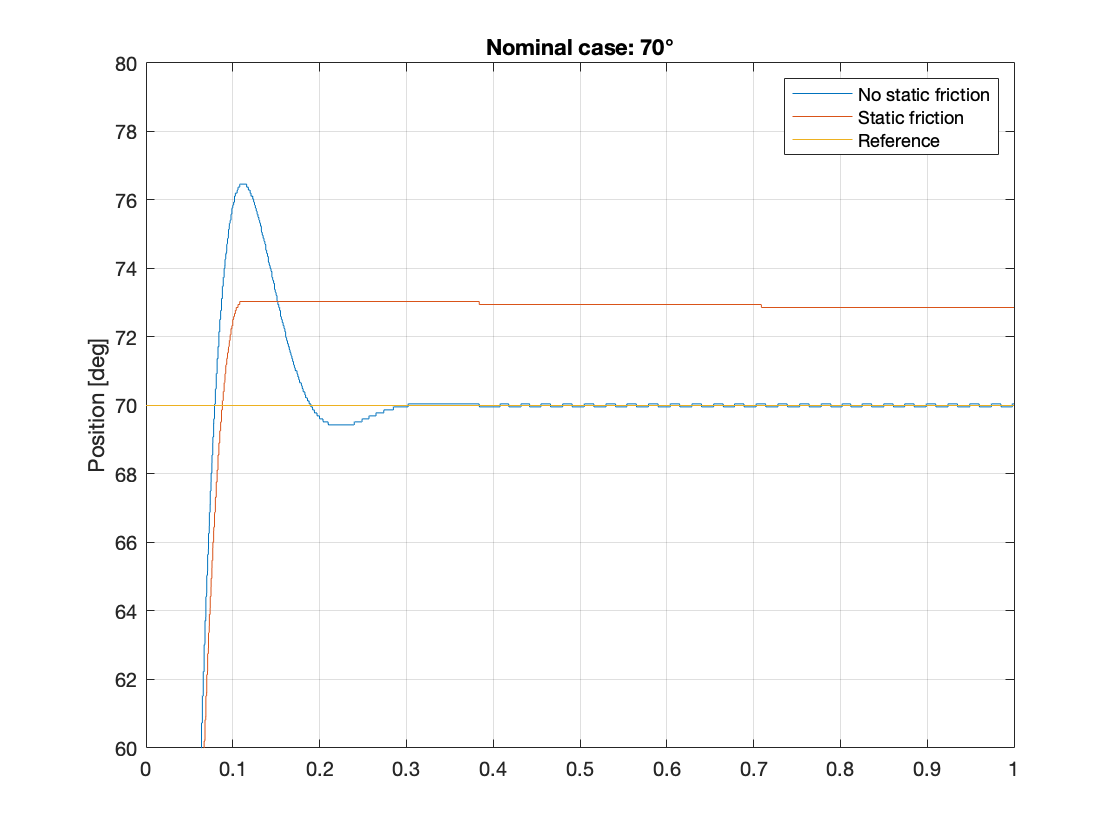

% Set parameters
% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','70');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','70');

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
nominal.t = simres.time; % time vector                        
nominal.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
nominal.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
nominal.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(4);
plot(nominal.t, nominal.thl_nsf);
hold on;
plot(nominal.t, nominal.thl_sf);
hold on;
plot(nominal.t, nominal.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([60,80]);
title('Nominal case: 70°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation results 120°

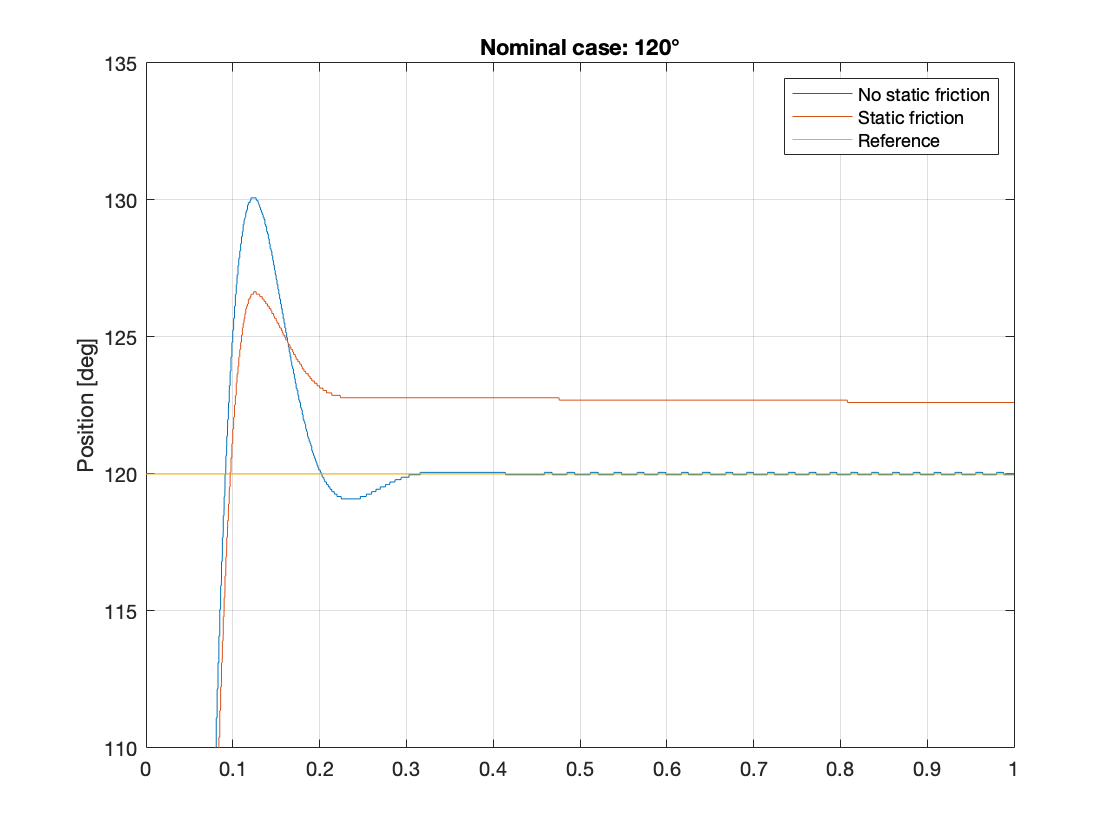

% Set parameters
% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','120');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','120');

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
nominal.t = simres.time; % time vector                        
nominal.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
nominal.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
nominal.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(5);
plot(nominal.t, nominal.thl_nsf);
hold on;
plot(nominal.t, nominal.thl_sf);
hold on;
plot(nominal.t, nominal.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([110,135]);
title('Nominal case: 120°');
legend('No static friction', 'Static friction', 'Reference');

## 2.  $\bf{State-Space\  Robust \ Control \ (Integral \ 
 action)}$

### 2.2.3

% Loading workspace variables
run('load_params_estimatedValues.m');
% Augmented state-space
robust.Ae = [0 state_space.C;[0;0] state_space.A];
robust.Be = [0;state_space.B];
robust.Ce = [0 state_space.C];

% Real and imaginary parts of the eigenvalues in (6) (in the assignment 1)
robust.sigma = -nominal.delta*nominal.wn;
robust.wd = nominal.wn*sqrt(1-nominal.delta^2);
% Pole placement
robust.poles1 = [robust.sigma + 1i*robust.wd, robust.sigma - 1i*robust.wd, robust.sigma];
robust.poles2 = [robust.sigma, robust.sigma, robust.sigma];
robust.poles3 = [2*robust.sigma + 1i*robust.wd, 2*robust.sigma - 1i*robust.wd, 2*robust.sigma];
robust.poles4 = [2*robust.sigma + 1i*robust.wd, 2*robust.sigma - 1i*robust.wd, 3*robust.sigma];

% Ke1
robust.Ke_1 = place(robust.Ae,robust.Be,robust.poles1);
robust.Ki_1 = robust.Ke_1(1);
robust.K_1 = robust.Ke_1(1,2:3);

% Ke2
robust.Ke_2 = acker(robust.Ae,robust.Be,robust.poles2);
robust.Ki_2 = robust.Ke_2(1);
robust.K_2 = robust.Ke_2(1,2:3);

% Ke3
robust.Ke_3 = place(robust.Ae,robust.Be,robust.poles3);
robust.Ki_3 = robust.Ke_3(1);
robust.K_3 = robust.Ke_3(1,2:3);

% Ke4
robust.Ke_4 = place(robust.Ae,robust.Be,robust.poles4);
robust.Ki_4 = robust.Ke_4(1);
robust.K_4 = robust.Ke_4(1,2:3);

### 2.2.4

#### Simulation results 40°

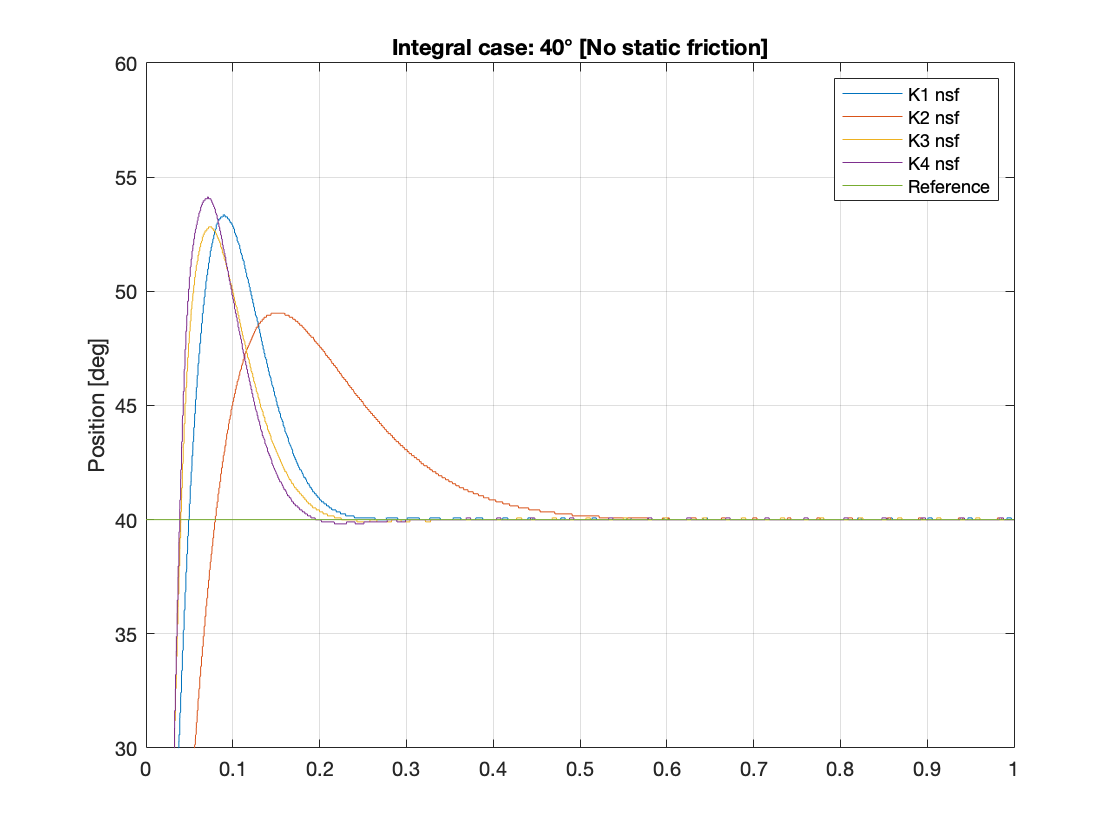

% Set parameters for K1
set_param('SS_Nominal_Integral', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '1');
% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','40');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','40');
% State-space Controller
set_param('SS_Nominal_Integral/State-space Controller/integral','sw','1'); % Integral action ON
set_param('SS_Nominal_Integral/State-space Controller1/integral','sw','1'); % Integral action ON
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_1'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_1'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_1');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_1');
% DC motor + gearbox
set_param('SS_Nominal_Integral/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Nominal_Integral/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction


% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results for K1
int_k1.t = simres.time; % time vector                        
int_k1.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k1.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
int_k1.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Set parameters for K2
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_2'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_2');
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_2');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_2'); 

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k2.t = simres.time; % time vector                        
int_k2.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k2.thl_sf = simres.signals(1).values(:,2); % load position (static friction)

% Set parameters for K3
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_3'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_3'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_3');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_3'); 

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k3.t = simres.time; % time vector                        
int_k3.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k3.thl_sf = simres.signals(1).values(:,2); % load position (static friction)

% Set parameters for K4
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_4'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_4'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_4');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_4');

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k4.t = simres.time; % time vector                        
int_k4.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k4.thl_sf = simres.signals(1).values(:,2); % load position (static friction)

% Plot simulation results (NO STATIC FRICTION)
figure(6);
plot(int_k1.t, int_k1.thl_nsf);
hold on;
plot(int_k2.t, int_k2.thl_nsf);
hold on;
grid on;
plot(int_k3.t, int_k3.thl_nsf);
hold on;
plot(int_k4.t, int_k4.thl_nsf);
hold on;
plot(int_k1.t, int_k1.thl_Ref);
ylabel('Position [deg]');
ylim([30,60]);
title('Integral case: 40° [No static friction]');
legend('K1 nsf','K2 nsf','K3 nsf','K4 nsf','Reference');


$$\bf{ Position\ state–space\ controller\ K3\ is\ the\ best\ choice}$$


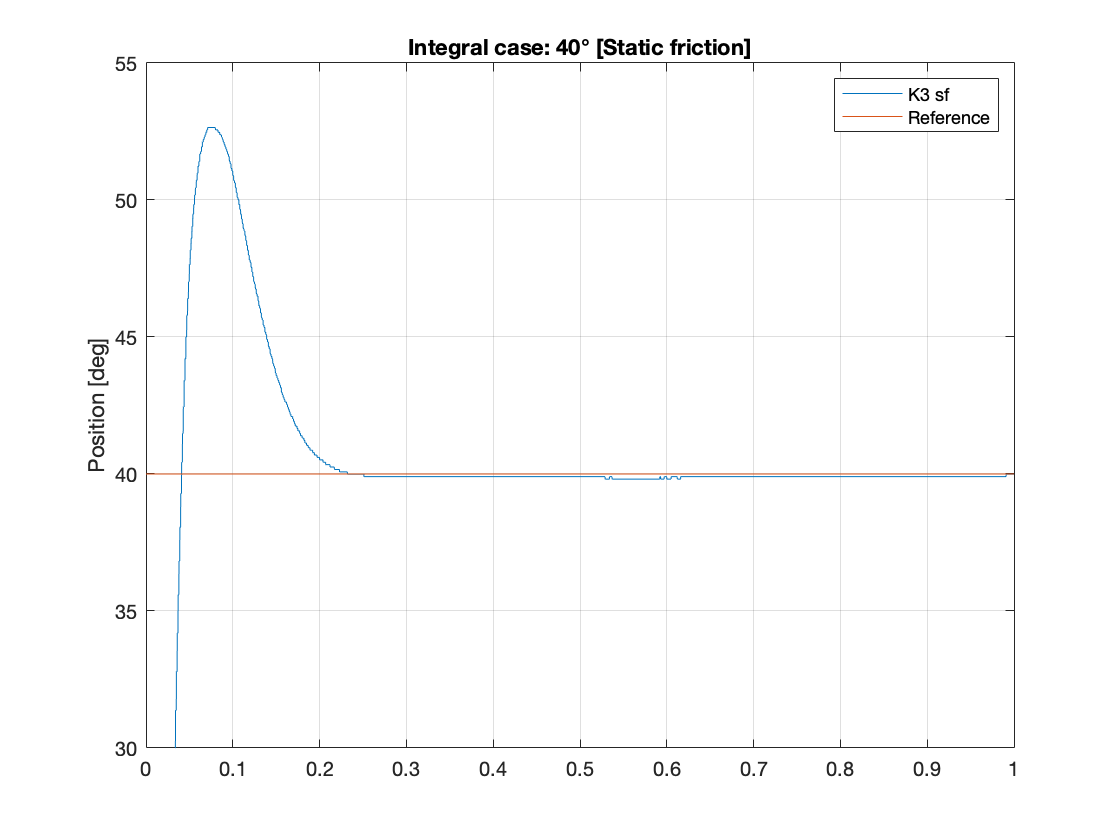

% Plot simulation results (STATIC FRICTION)
figure(7);
plot(int_k3.t, int_k3.thl_sf);
hold on;
plot(int_k1.t, int_k1.thl_Ref);
ylabel('Position [deg]');
ylim([30,55]);
grid on;
title('Integral case: 40° [Static friction]');
legend('K3 sf','Reference');

### Simulation results 70°

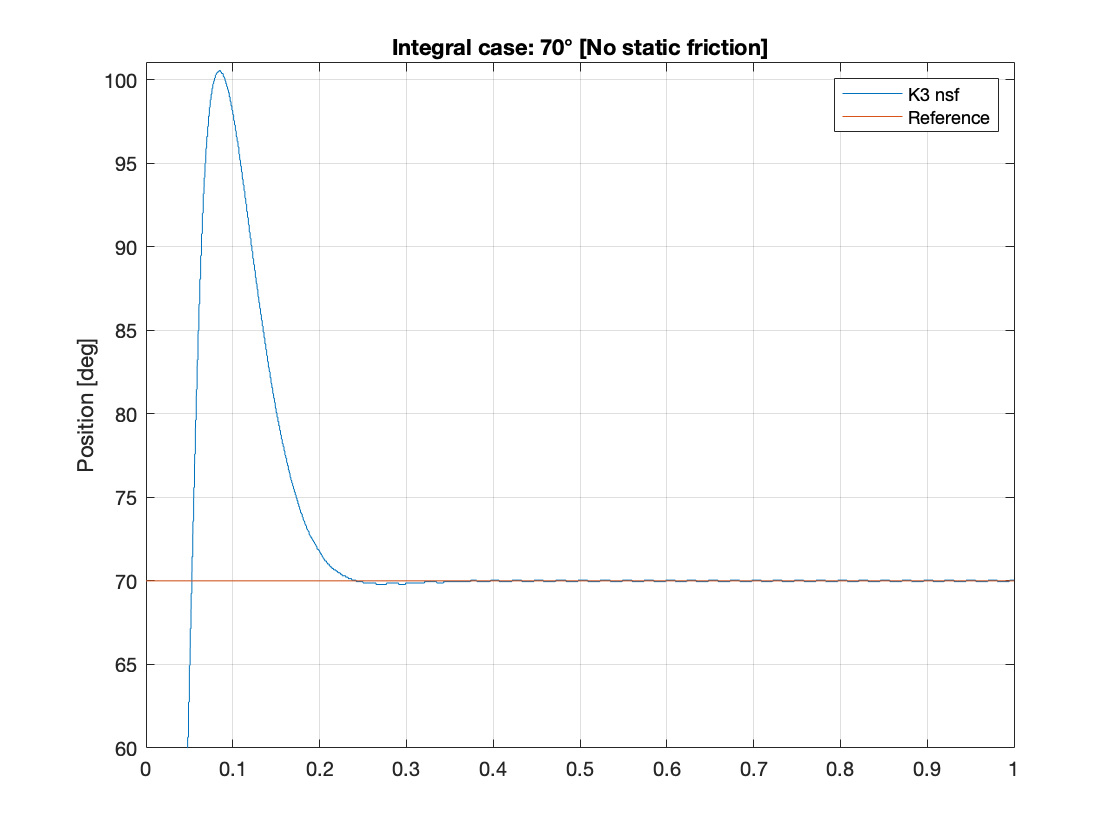

% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','70');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','70');
% State-space Controller
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_3'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_3');
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_3');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_3'); 

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k3.t = simres.time; % time vector                        
int_k3.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k3.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
int_k3.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results (NO STATIC FRICTION)
figure(8);
plot(int_k3.t, int_k3.thl_nsf);
hold on;
plot(int_k3.t, int_k3.thl_Ref);
ylabel('Position [deg]');
ylim([60,101]);
grid on;
title('Integral case: 70° [No static friction]');
legend('K3 nsf','Reference');

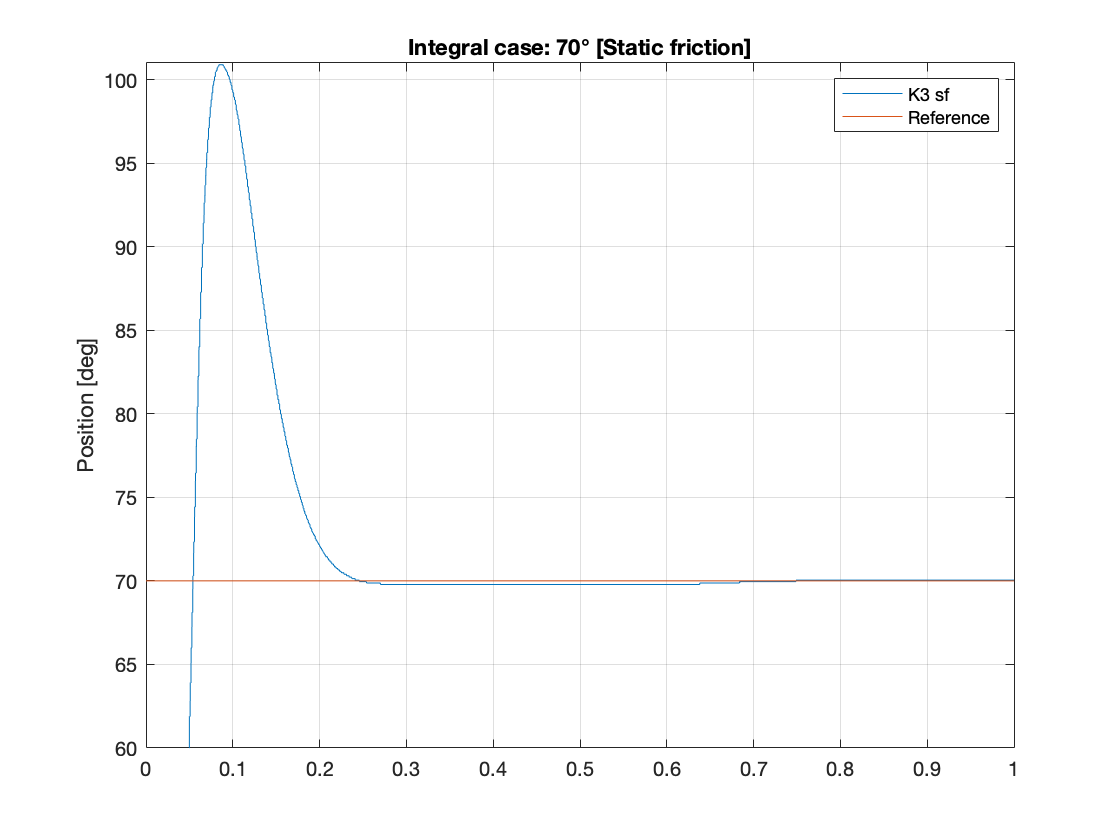

% Plot simulation results (STATIC FRICTION)
figure(9);
plot(int_k3.t, int_k3.thl_sf);
hold on;
plot(int_k3.t, int_k3.thl_Ref);
ylabel('Position [deg]');
ylim([60,101]);
grid on;
title('Integral case: 70° [Static friction]');
legend('K3 sf','Reference');

#### Simulation results 120°

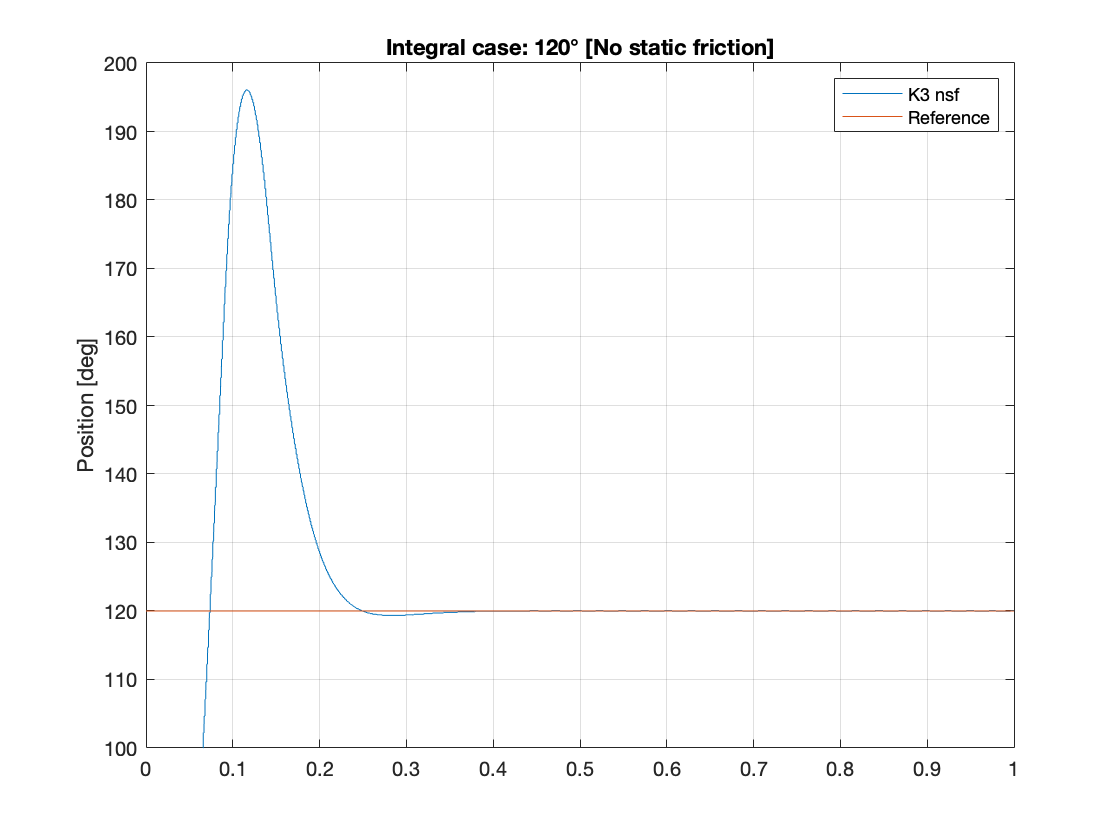

% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','120');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','120');

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k3.t = simres.time; % time vector                        
int_k3.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k3.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
int_k3.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results (NO STATIC FRICTION)
figure(10);
plot(int_k3.t, int_k3.thl_nsf);
hold on;
plot(int_k3.t, int_k3.thl_Ref);
ylabel('Position [deg]');
ylim([100,200]);
grid on;
title('Integral case: 120° [No static friction]');
legend('K3 nsf','Reference');

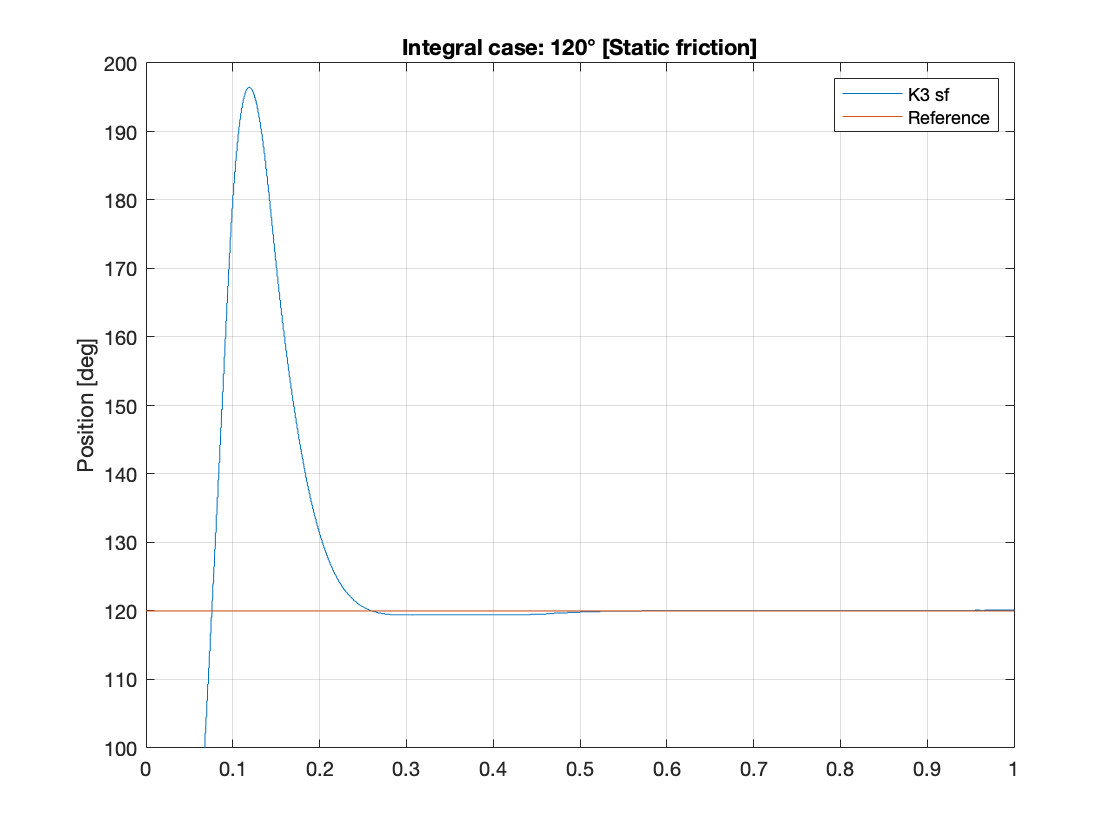

% Plot simulation results (STATIC FRICTION)
figure(11);
plot(int_k3.t, int_k3.thl_sf);
hold on;
plot(int_k3.t, int_k3.thl_Ref);
ylabel('Position [deg]');
ylim([100,200]);
grid on;
title('Integral case: 120° [Static friction]');
legend('K3 sf','Reference');

## 3.  $\bf{State-Space\  Robust \ Control \ (Error \ 
 space)}$

### 2.2.5

% Loading workspace variables
run('load_params_estimatedValues.m');

% Periods and frequencies
err_space.Tr1 = 0.15;
err_space.Tr2 = 0.25;
err_space.Tr3 = 0.5;
err_space.Tr4 = 1;
err_space.w1 = 2*pi/err_space.Tr1;
err_space.w2 = 2*pi/err_space.Tr2;
err_space.w3 = 2*pi/err_space.Tr3;
err_space.w4 = 2*pi/err_space.Tr4;

% Az_1
err_space.A11_1 = [0 1 0;0 0 1;0 -err_space.w1^2 0];
err_space.A12_1 = [0 0;0 0; state_space.C];
err_space.A21_1 = [0 0 0;0 0 0];
err_space.A22_1 = state_space.A;
err_space.Az_1 = [err_space.A11_1 err_space.A12_1;err_space.A21_1 err_space.A22_1];

% Az_2
err_space.A11_2 = [0 1 0;0 0 1;0 -err_space.w2^2 0];
err_space.A12_2 = [0 0;0 0; state_space.C];
err_space.A21_2 = [0 0 0;0 0 0];
err_space.A22_2 = state_space.A;
err_space.Az_2 = [err_space.A11_2 err_space.A12_2;err_space.A21_2 err_space.A22_2];

% Az_3
err_space.A11_3 = [0 1 0;0 0 1;0 -err_space.w3^2 0];
err_space.A12_3 = [0 0;0 0; state_space.C];
err_space.A21_3 = [0 0 0;0 0 0];
err_space.A22_3 = state_space.A;
err_space.Az_3 = [err_space.A11_3 err_space.A12_3;err_space.A21_3 err_space.A22_3];

% Az_4
err_space.A11_4 = [0 1 0;0 0 1;0 -err_space.w4^2 0];
err_space.A12_4 = [0 0;0 0; state_space.C];
err_space.A21_4 = [0 0 0;0 0 0];
err_space.A22_4 = state_space.A;
err_space.Az_4 = [err_space.A11_4 err_space.A12_4;err_space.A21_4 err_space.A22_4];

% Bz
err_space.Bz = [0;0;0;state_space.B];

% Desired eigenvalues
err_space.p1 = nominal.wn*exp(1i*(-pi + pi/4));
err_space.p2 = conj(err_space.p1);
err_space.p3 = nominal.wn*exp(1i*(-pi + pi/6));
err_space.p4 = conj(err_space.p3);
err_space.p5 = -nominal.wn;
err_space.eigs = [err_space.p1 err_space.p2 err_space.p3 err_space.p4 err_space.p5];

% Kz_1, Kpsi_1, Hnum_1, Hden_1
err_space.Kz_1 = place(err_space.Az_1,err_space.Bz,err_space.eigs);
err_space.Kpsi_1 = err_space.Kz_1(1,4:5);
err_space.Hnum_1 = [err_space.Kz_1(1,3) err_space.Kz_1(1,2) err_space.Kz_1(1,1)];
err_space.Hden_1 = [1 0 err_space.w1^2 0];

% Kz_2, Kpsi_2, Hnum_2, Hden_2
err_space.Kz_2 = place(err_space.Az_2,err_space.Bz,err_space.eigs);
err_space.Kpsi_2 = err_space.Kz_2(1,4:5);
err_space.Hnum_2 = [err_space.Kz_2(1,3) err_space.Kz_2(1,2) err_space.Kz_2(1,1)];
err_space.Hden_1 = [1 0 err_space.w2^2 0];

% Kz_3, Kpsi_3, Hnum_3, Hden_3
err_space.Kz_3 = place(err_space.Az_3,err_space.Bz,err_space.eigs);
err_space.Kpsi_3 = err_space.Kz_3(1,4:5);
err_space.Hnum_3 = [err_space.Kz_3(1,3) err_space.Kz_3(1,2) err_space.Kz_3(1,1)];
err_space.Hden_3 = [1 0 err_space.w3^2 0];

% Kz_4, Kpsi_4, Hnum_4, Hden_4
err_space.Kz_4 = place(err_space.Az_4,err_space.Bz,err_space.eigs);
err_space.Kpsi_4 = err_space.Kz_4(1,4:5);
err_space.Hnum_4 = [err_space.Kz_4(1,3) err_space.Kz_4(1,2) err_space.Kz_4(1,1)];
err_space.Hden_4 = [1 0 err_space.w4^2 0];

### 2.2.6 

#### Simulation 30°

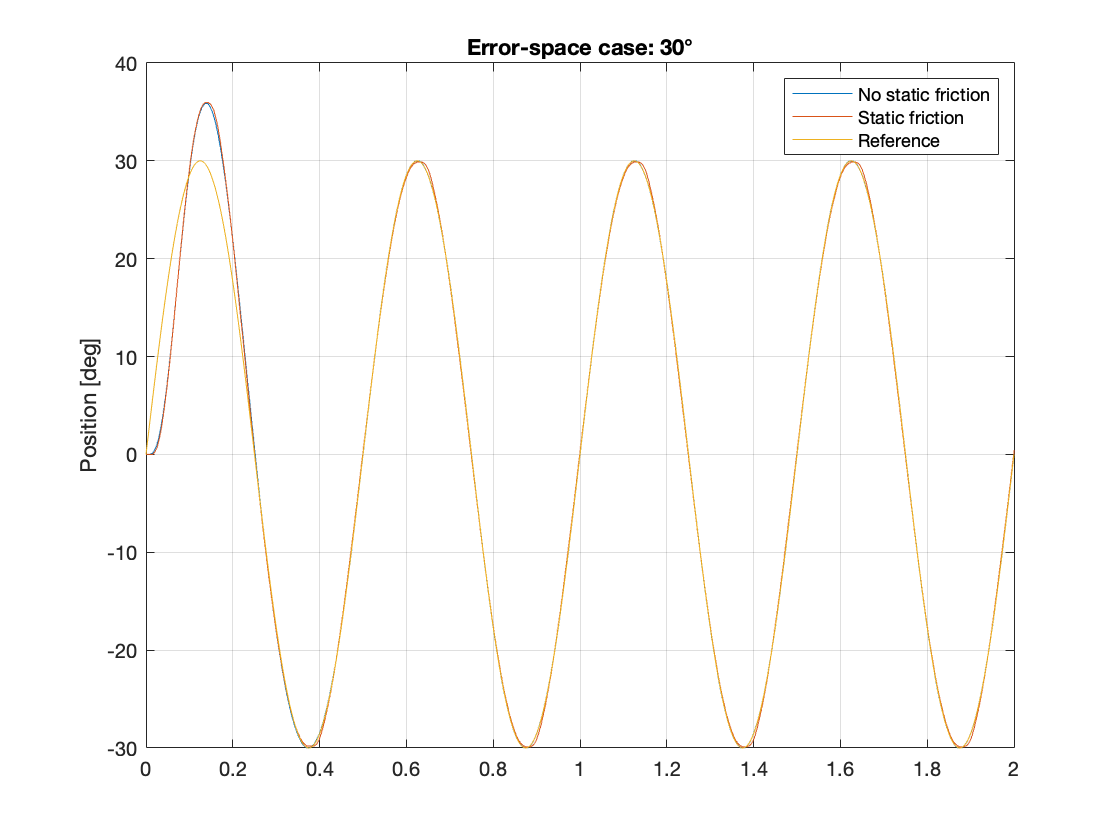

% Open Simulink model
open_system('Simulink/SS_Error_space.slx');

% Set parameters
set_param('SS_Error_space', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2');
% Ref & Ref1 
set_param('SS_Error_space/Sine','Amplitude','30','Frequency','err_space.w3');
set_param('SS_Error_space/Sine1','Amplitude','30','Frequency','err_space.w3');
set_param('SS_Error_space/switch','sw','1');
set_param('SS_Error_space/switch1','sw','1');
% State-space Controller
set_param('SS_Error_space/State-space Controller/tf','Numerator','err_space.Hnum_3');
set_param('SS_Error_space/State-space Controller1/tf','Numerator','err_space.Hnum_3');
set_param('SS_Error_space/State-space Controller/tf','Denominator','err_space.Hden_3');
set_param('SS_Error_space/State-space Controller1/tf','Denominator','err_space.Hden_3');
set_param('SS_Error_space/State-space Controller/k','Gain','err_space.Kpsi_3','Multiplication','Matrix(K*u)'); 
set_param('SS_Error_space/State-space Controller1/k','Gain','err_space.Kpsi_3','Multiplication','Matrix(K*u)'); 
% DC motor + gearbox
set_param('SS_Error_space/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Error_space/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = simres.time; % time vector                        
err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(12);
plot(err_space.t, err_space.thl_nsf);
hold on;
plot(err_space.t, err_space.thl_sf);
hold on;
plot(err_space.t, err_space.thl_Ref);
ylabel('Position [deg]');
grid on;
%ylim([20,40]);
title('Error-space case: 30°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation 60°

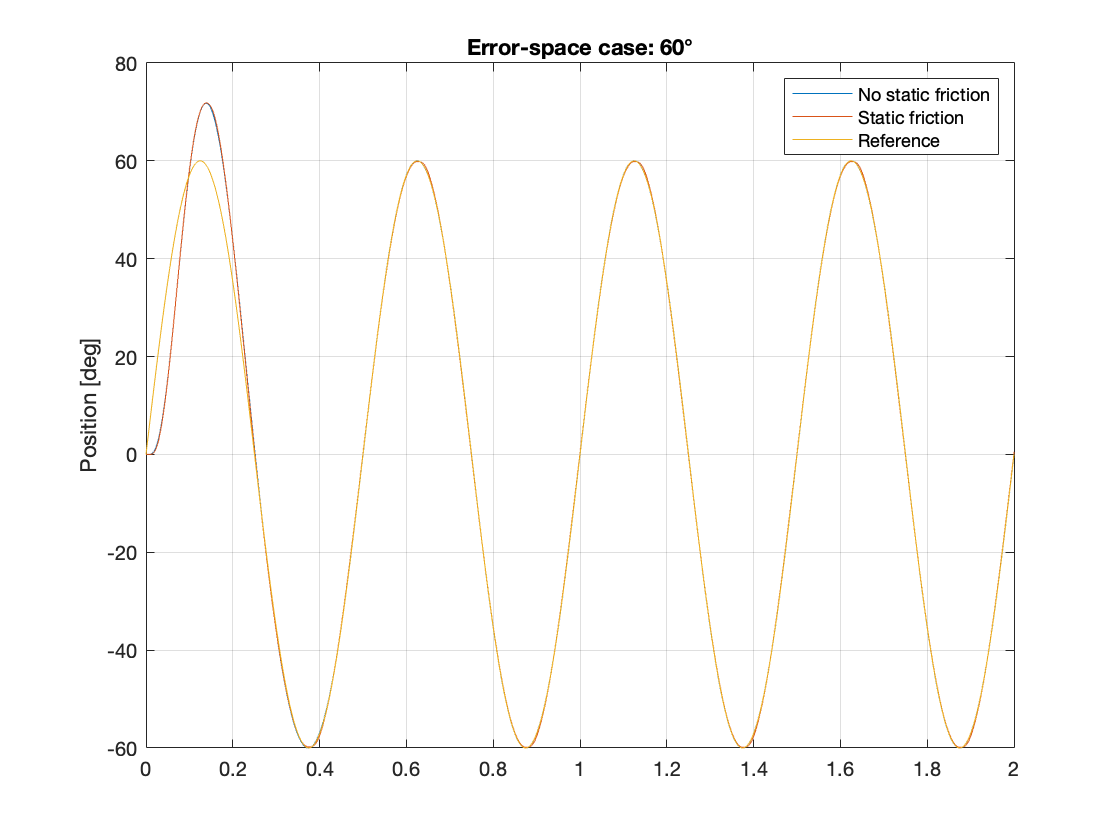

% Ref & Ref1 
set_param('SS_Error_space/Sine','Amplitude','60','Frequency','err_space.w3');
set_param('SS_Error_space/Sine1','Amplitude','60','Frequency','err_space.w3');

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = simres.time; % time vector                        
err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(13);
plot(err_space.t, err_space.thl_nsf);
hold on;
plot(err_space.t, err_space.thl_sf);
hold on;
plot(err_space.t, err_space.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Error-space case: 60°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation 90°

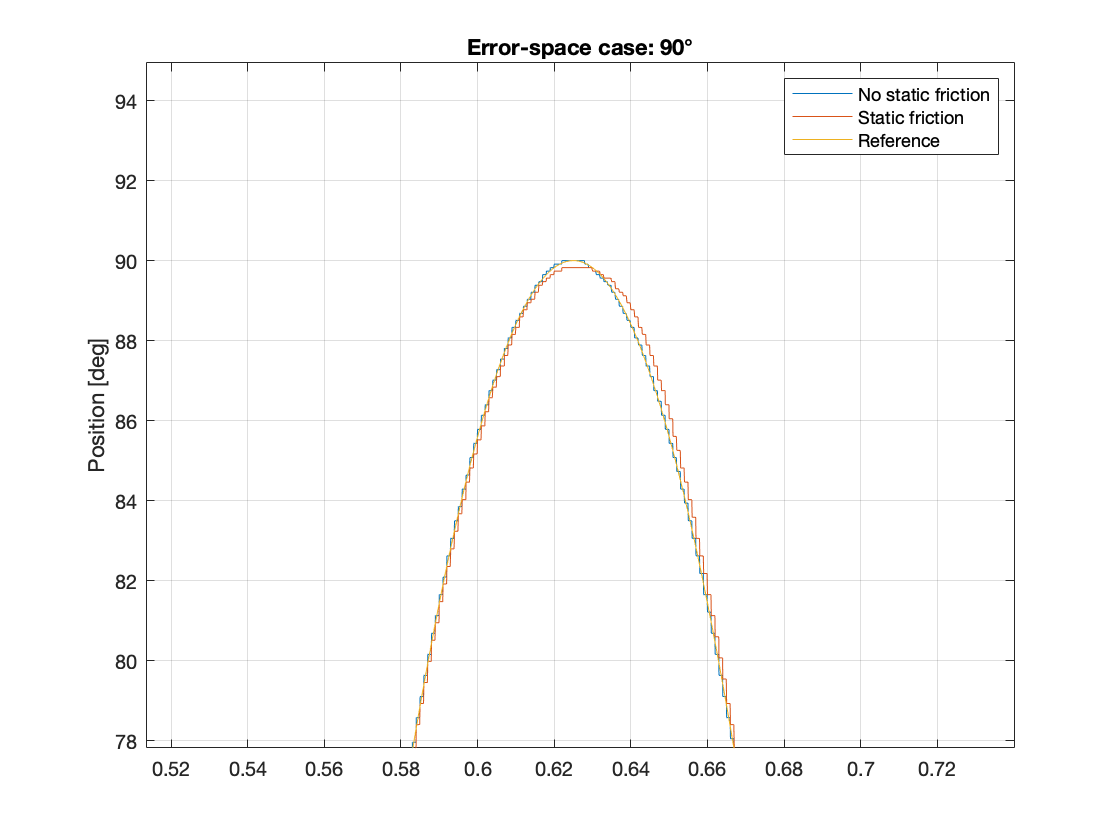

% Ref & Ref1 
set_param('SS_Error_space/Sine','Amplitude','90','Frequency','err_space.w3');
set_param('SS_Error_space/Sine1','Amplitude','90','Frequency','err_space.w3');

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = simres.time; % time vector                        
err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(14);
plot(err_space.t, err_space.thl_nsf);
hold on;
plot(err_space.t, err_space.thl_sf);
hold on;
plot(err_space.t, err_space.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Error-space case: 90°');
legend('No static friction', 'Static friction', 'Reference');

### 2.2.7 

#### Simulation (Tracking of sine (T=0.1) with controller K3)

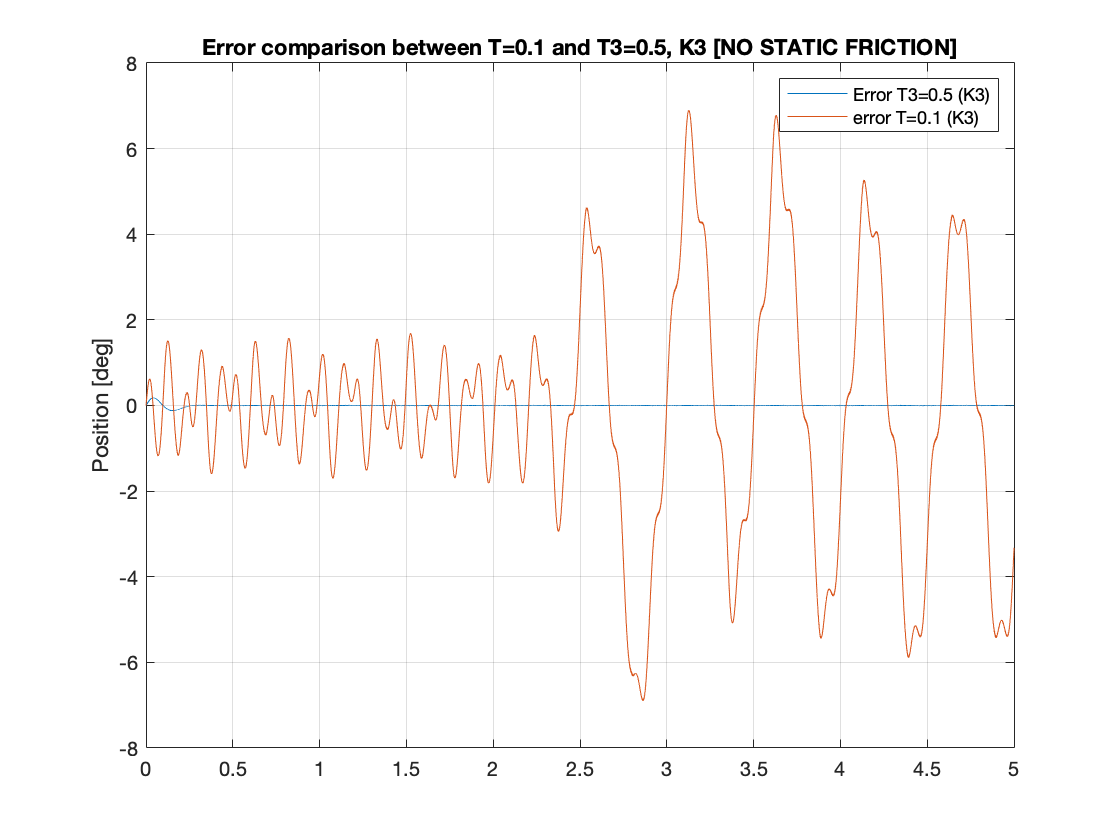

% Set parameters
set_param('SS_Error_space', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '5');
% Ref & Ref1 
set_param('SS_Error_space/Sine','Amplitude','30','Frequency','err_space.w3');
set_param('SS_Error_space/Sine1','Amplitude','40','Frequency','2*pi/0.1');
% DC motor + gearbox
set_param('SS_Error_space/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Error_space/DC motor + gearbox1/static','Gain','0'); % No static friction

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = err.time; % time vector                        
err_space.err_thl_nsf_w3 = err.signals(1).values(:,1); % load position (no static friction)
err_space.err_thl_nsf_01 = err.signals(1).values(:,2); % load position (static friction)

%err_space.t = simres.time; % time vector                        
%err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
%err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
%err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(15);
plot(err_space.t, err_space.err_thl_nsf_w3);
hold on;
plot(err_space.t, err_space.err_thl_nsf_01);
ylabel('Position [deg]');
grid on;
title('Error comparison between T=0.1 and T3=0.5, K3 [NO STATIC FRICTION]');
legend('Error T3=0.5 (K3)', 'error T=0.1 (K3)');

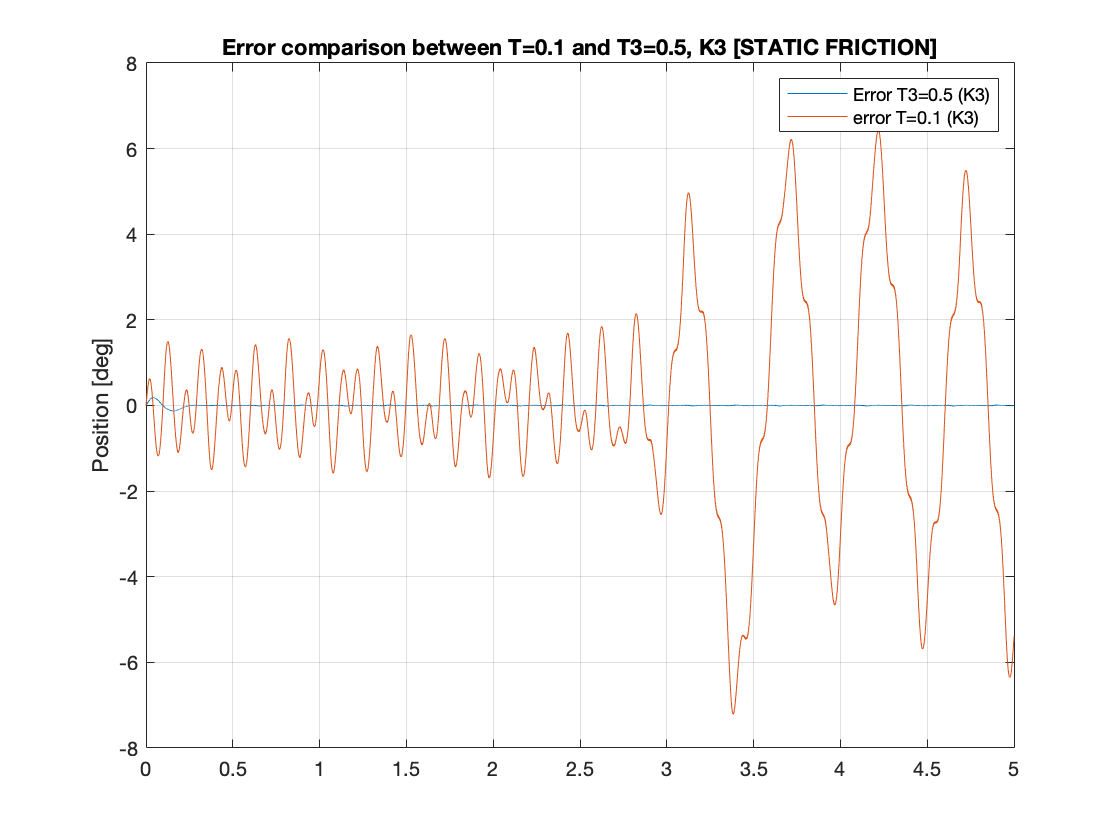

% DC motor + gearbox
set_param('SS_Error_space/DC motor + gearbox/static','Gain','est_par.tau_sf'); % Static friction
set_param('SS_Error_space/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = err.time; % time vector                        
err_space.err_thl_sf_w3 = err.signals(1).values(:,1); % load position (no static friction)
err_space.err_thl_sf_01 = err.signals(1).values(:,2); % load position (static friction)

%err_space.t = simres.time; % time vector                        
%err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
%err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
%err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(16);
plot(err_space.t, err_space.err_thl_sf_w3);
hold on;
plot(err_space.t, err_space.err_thl_sf_01);
ylabel('Position [deg]');
grid on;
title('Error comparison between T=0.1 and T3=0.5, K3 [STATIC FRICTION]');
legend('Error T3=0.5 (K3)', 'error T=0.1 (K3)');

### 2.2.8 

#### Simulation (Tracking of step with controller K3)

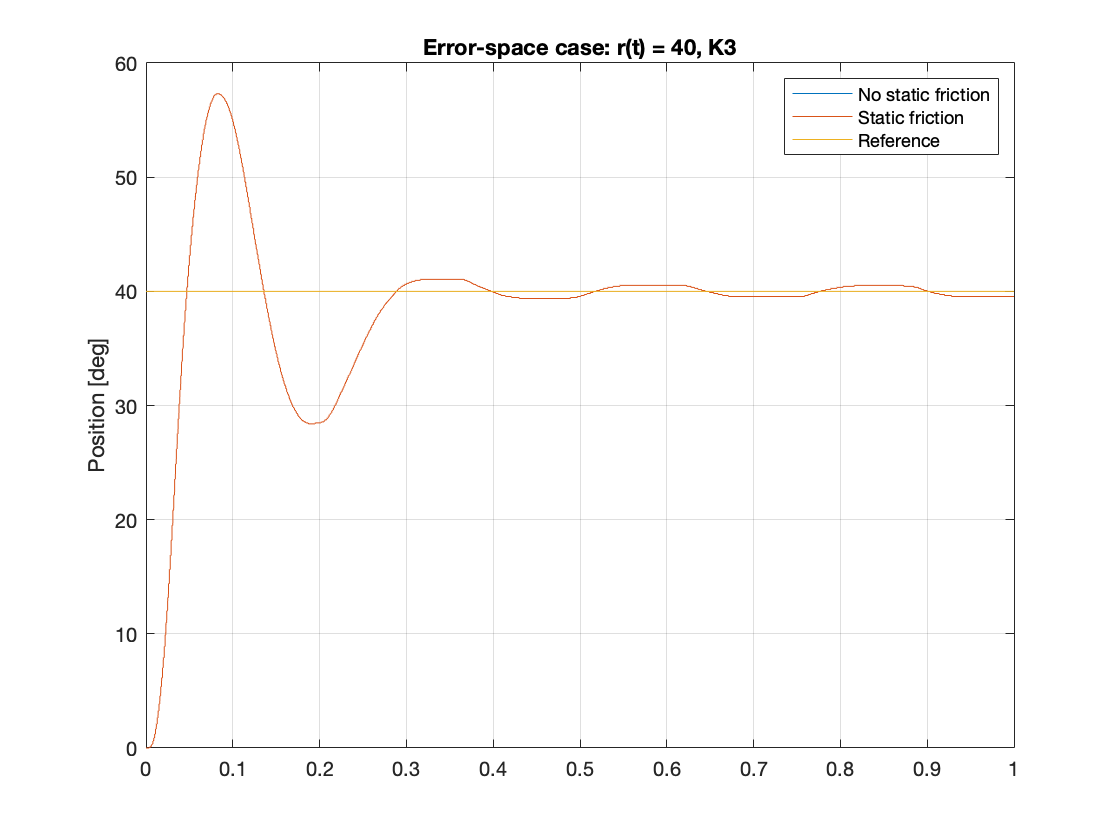

% Set parameters
set_param('SS_Error_space', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '1');
% Ref & Ref1 
set_param('SS_Error_space/step','Time','0','After','40');
set_param('SS_Error_space/step1','Time','0','After','40');
set_param('SS_Error_space/switch','sw','0');
set_param('SS_Error_space/switch1','sw','0');

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = simres.time; % time vector                        
err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(17);
plot(err_space.t, err_space.thl_nsf);
hold on;
plot(err_space.t, err_space.thl_sf);
hold on;
plot(err_space.t, err_space.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Error-space case: r(t) = 40, K3');
legend('No static friction', 'Static friction', 'Reference');

## 3.  $\bf{State-Space\  Robust \ Control \ (Extended-state \ estimator) \ OPTIONAL \  PART}$

### 2.2.9 

% Ae_1
ss_est.Ae11_1 = [0 1 0;0 0 1;0 -err_space.w1^2 0];
ss_est.Ae12_1 = [0 0;0 0;0 0];
ss_est.Ae21_1 = state_space.B * [1 0 0];
ss_est.Ae22_1 = state_space.A;
ss_est.Ae_1 = [ss_est.Ae11_1 ss_est.Ae12_1;ss_est.Ae21_1 ss_est.Ae22_1];

% Ae_2
ss_est.Ae11_2 = [0 1 0;0 0 1;0 -err_space.w2^2 0];
ss_est.Ae12_2 = [0 0;0 0;0 0];
ss_est.Ae21_2 = state_space.B * [1 0 0];
ss_est.Ae22_2 = state_space.A;
ss_est.Ae_2 = [ss_est.Ae11_2 ss_est.Ae12_2;ss_est.Ae21_2 ss_est.Ae22_2];

% Ae_3
ss_est.Ae11_3 = [0 1 0;0 0 1;0 -err_space.w3^2 0];
ss_est.Ae12_3 = [0 0;0 0;0 0];
ss_est.Ae21_3 = state_space.B * [1 0 0];
ss_est.Ae22_3 = state_space.A;
ss_est.Ae_3 = [ss_est.Ae11_3 ss_est.Ae12_3;ss_est.Ae21_3 ss_est.Ae22_3];

% Ae_4
ss_est.Ae11_4 = [0 1 0;0 0 1;0 -err_space.w4^2 0];
ss_est.Ae12_4 = [0 0;0 0;0 0];
ss_est.Ae21_4 = state_space.B * [1 0 0];
ss_est.Ae22_4 = state_space.A;
ss_est.Ae_4 = [ss_est.Ae11_4 ss_est.Ae12_4;ss_est.Ae21_4 ss_est.Ae22_4];

% Be
ss_est.Be = [0;0;0;state_space.B];

% Ce
ss_est.Ce = [0 0 0 state_space.C];

% Desired eigenvalues of the estimator
ss_est.e1 = 2*nominal.wn*exp(1i*(-pi + pi/3));
ss_est.e2 = conj(ss_est.e1);
ss_est.e3 = 2*nominal.wn*exp(1i*(-pi + pi/6));
ss_est.e4 = conj(ss_est.e3);
ss_est.e5 = -2*nominal.wn;
ss_est.e_eigs = [ss_est.e1 ss_est.e2 ss_est.e3 ss_est.e4 ss_est.e5];

% Desired eigenvalues of the controller
ss_est.c1 = -nominal.delta*nominal.wn + 1i*nominal.wn*sqrt(1-nominal.delta^2);
ss_est.c2 = conj(ss_est.c1);
ss_est.c_eigs = [ss_est.c1 ss_est.c2];

% Le_1
ss_est.Le_1 = transpose(place(transpose(ss_est.Ae_1),transpose(ss_est.Ce),ss_est.e_eigs));

% Le_2
ss_est.Le_2 = transpose(place(transpose(ss_est.Ae_2),transpose(ss_est.Ce),ss_est.e_eigs));

% Le_3
ss_est.Le_3 = transpose(place(transpose(ss_est.Ae_3),transpose(ss_est.Ce),ss_est.e_eigs));

% Le_4
ss_est.Le_4 = transpose(place(transpose(ss_est.Ae_4),transpose(ss_est.Ce),ss_est.e_eigs));

% K
ss_est.K = place(state_space.A, state_space.B,ss_est.c_eigs);

### 2.2.10 (Repeat point 2.2.6)

% Open Simulink model
open_system('Simulink/SS_Extended_Est.slx');

% Set parameters
set_param('SS_Extended_Est', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '1');

#### Simulation 30°

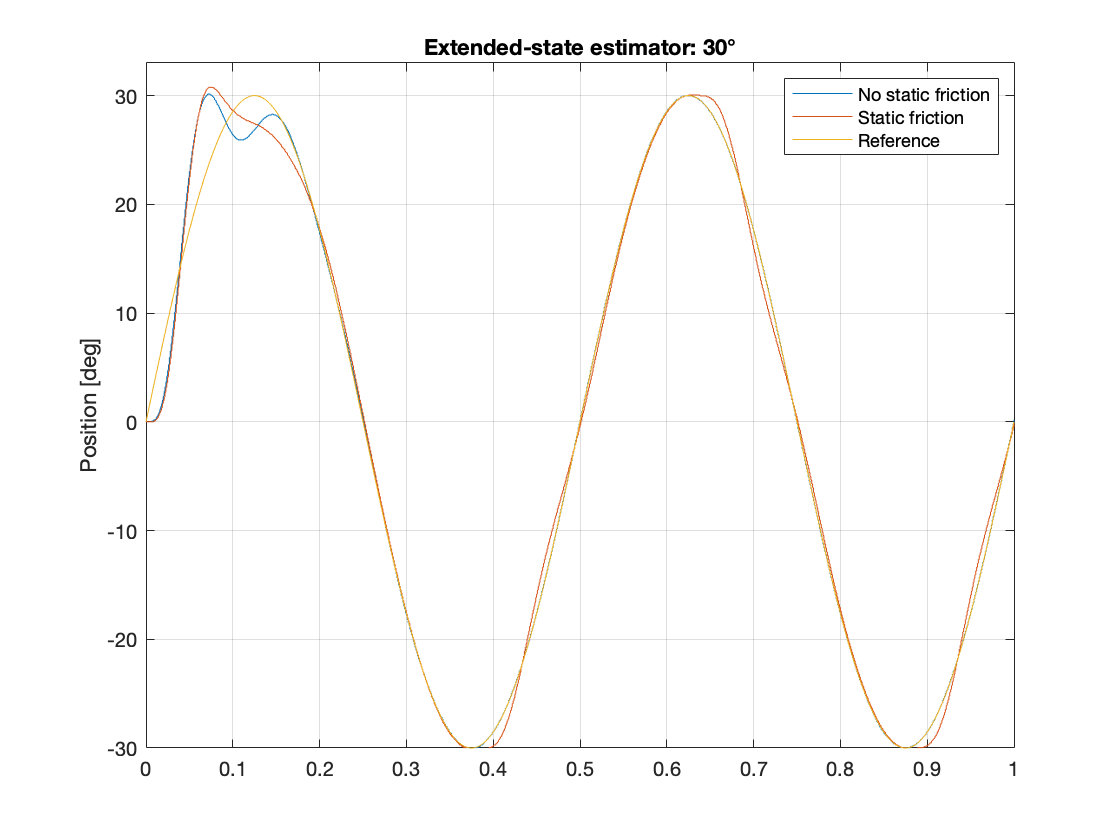

% Ref & Ref1 
set_param('SS_Extended_Est/step','Time','0','Before','0','After','40');
set_param('SS_Extended_Est/step1','Time','0','Before','0','After','40');
set_param('SS_Extended_Est/sine','Amplitude','30','Frequency','err_space.w3');
set_param('SS_Extended_Est/sine1','Amplitude','30','Frequency','err_space.w3');
set_param('SS_Extended_Est/switch','sw','1');
set_param('SS_Extended_Est/switch1','sw','1');
% Full order state observer
set_param('SS_Extended_Est/Full Order Observer','A','ss_est.Ae_3 - ss_est.Le_3*ss_est.Ce'); 
set_param('SS_Extended_Est/Full Order Observer1','A','ss_est.Ae_3 - ss_est.Le_3*ss_est.Ce');
set_param('SS_Extended_Est/Full Order Observer','B','[ss_est.Be ss_est.Le_3]'); 
set_param('SS_Extended_Est/Full Order Observer1','B','[ss_est.Be ss_est.Le_3]'); 
set_param('SS_Extended_Est/Full Order Observer','C','eye(5)'); 
set_param('SS_Extended_Est/Full Order Observer1','C','eye(5)'); 
set_param('SS_Extended_Est/Full Order Observer','D','[0 0; 0 0;0 0;0 0;0 0]'); 
set_param('SS_Extended_Est/Full Order Observer1','D','[0 0; 0 0;0 0;0 0;0 0]');
% State feedback gain
set_param('SS_Extended_Est/K','Gain','ss_est.K');
% C_rho
set_param('SS_Extended_Est/C_rho','Gain','[1 0 0]');
% DC motor + gearbox
set_param('SS_Extended_Est/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Extended_Est/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Extended_Est');

% Extract simulation results
ss_est.t = simres.time; % time vector                        
ss_est.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
ss_est.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
ss_est.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(18);
plot(ss_est.t, ss_est.thl_nsf);
hold on;
plot(ss_est.t, ss_est.thl_sf);
hold on;
plot(ss_est.t, ss_est.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([-30,33]);
title('Extended-state estimator: 30°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation 60°

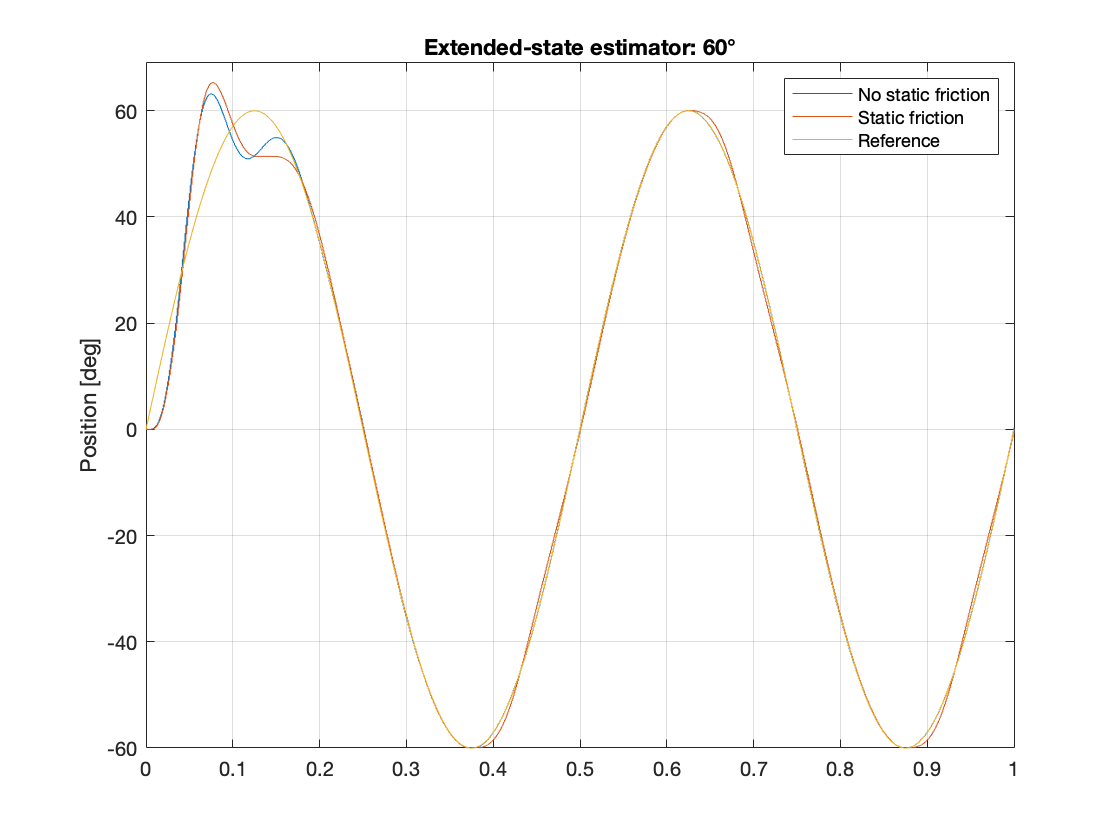

% Ref & Ref1 
set_param('SS_Extended_Est/sine','Amplitude','60','Frequency','err_space.w3');
set_param('SS_Extended_Est/sine1','Amplitude','60','Frequency','err_space.w3');

% Run simulation
sim('SS_Extended_Est');

% Extract simulation results
ss_est.t = simres.time; % time vector                        
ss_est.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
ss_est.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
ss_est.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(19);
plot(ss_est.t, ss_est.thl_nsf);
hold on;
plot(ss_est.t, ss_est.thl_sf);
hold on;
plot(ss_est.t, ss_est.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([-60,69]);
title('Extended-state estimator: 60°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation 90°

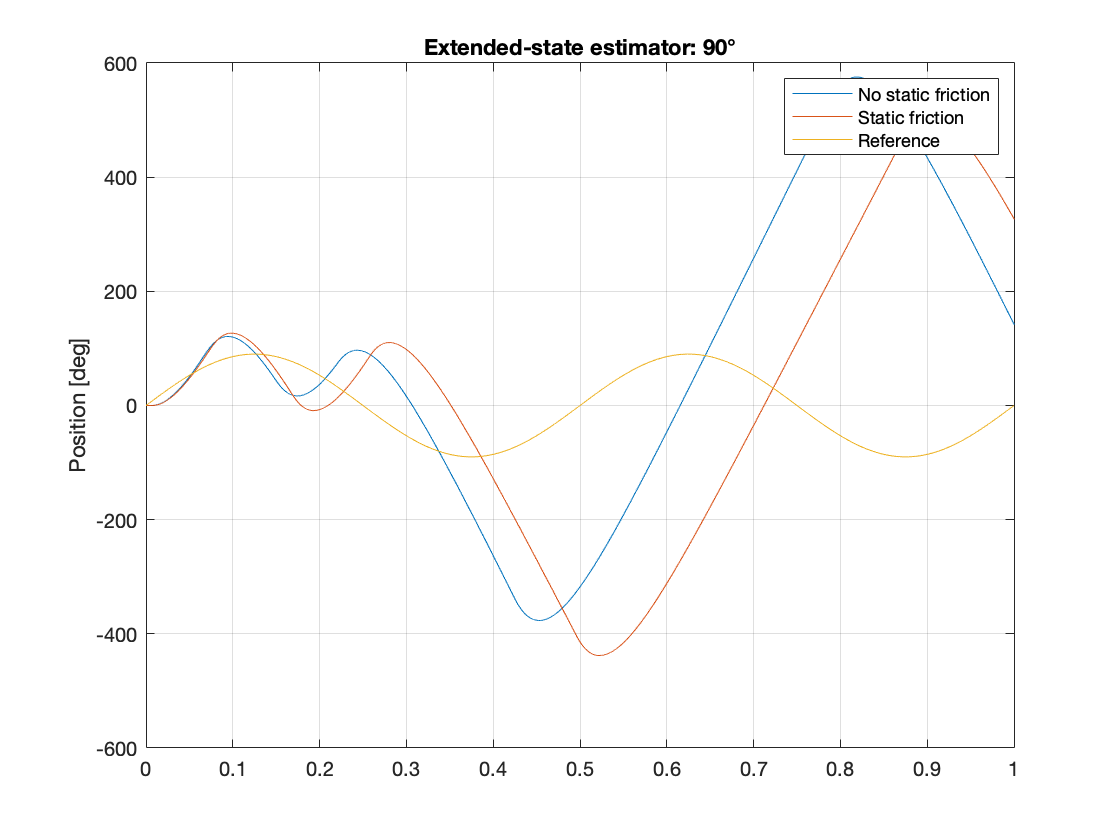

% Ref & Ref1 
set_param('SS_Extended_Est/sine','Amplitude','90','Frequency','err_space.w3');
set_param('SS_Extended_Est/sine1','Amplitude','90','Frequency','err_space.w3');

% Run simulation
sim('SS_Extended_Est');

% Extract simulation results
ss_est.t = simres.time; % time vector                        
ss_est.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
ss_est.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
ss_est.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(20);
plot(ss_est.t, ss_est.thl_nsf);
hold on;
plot(ss_est.t, ss_est.thl_sf);
hold on;
plot(ss_est.t, ss_est.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([-600,600]);
title('Extended-state estimator: 90°');
legend('No static friction', 'Static friction', 'Reference');

### 2.2.10 (Repeat point 2.2.7)

#### Simulation (Tracking of sine (T=0.1) with observer gain L3)

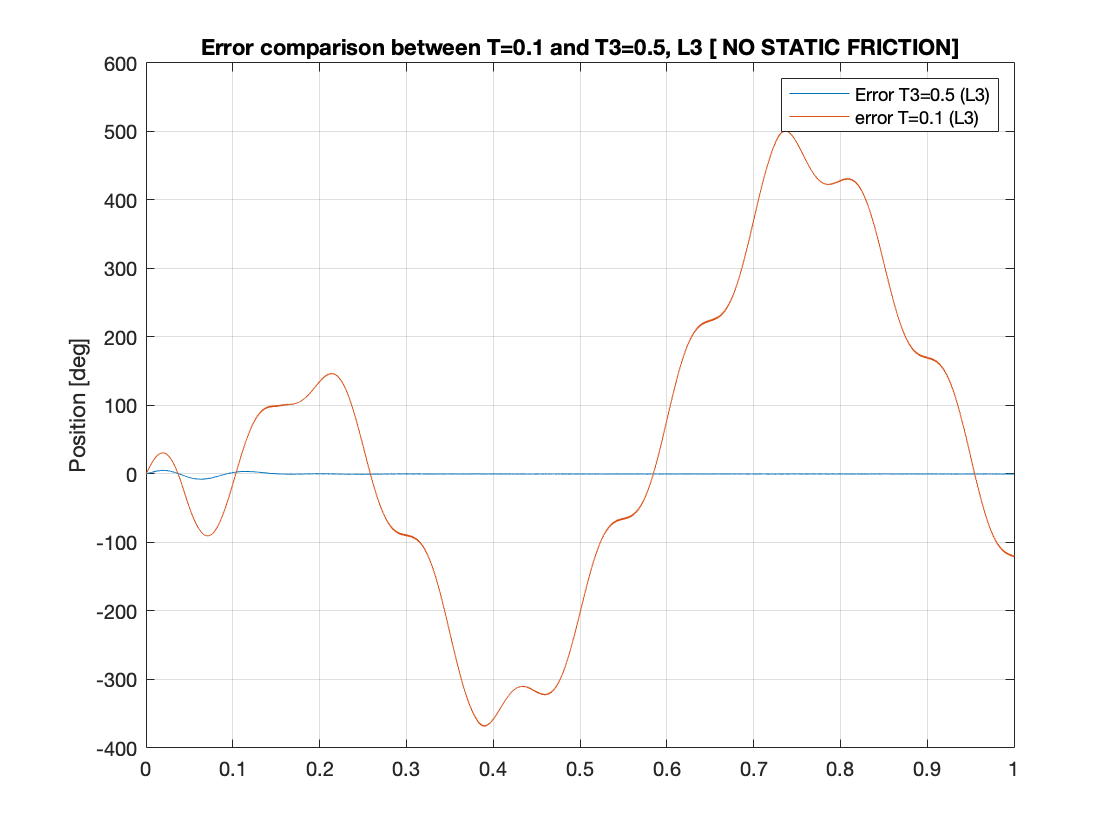

% Ref & Ref1 
set_param('SS_Extended_Est/sine','Amplitude','30','Frequency','err_space.w3');
set_param('SS_Extended_Est/sine1','Amplitude','40','Frequency','2*pi/0.1');
% DC motor + gearbox
set_param('SS_Error_space/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Error_space/DC motor + gearbox1/static','Gain','0'); % No static friction
% Run simulation
sim('SS_Extended_Est');

% Extract simulation results
ss_est.err_t = err.time; % time vector                        
ss_est.err_thl_nsf_w3 = err.signals(1).values(:,1); % load position (no static friction)
ss_est.err_thl_nsf_01 = err.signals(1).values(:,2); % load position (static friction)

% Plot simulation results
figure(21);
plot(ss_est.err_t, ss_est.err_thl_nsf_w3);
hold on;
plot(ss_est.err_t, ss_est.err_thl_nsf_01);
ylabel('Position [deg]');
grid on;
title('Error comparison between T=0.1 and T3=0.5, L3 [ NO STATIC FRICTION]');
legend('Error T3=0.5 (L3)', 'error T=0.1 (L3)');

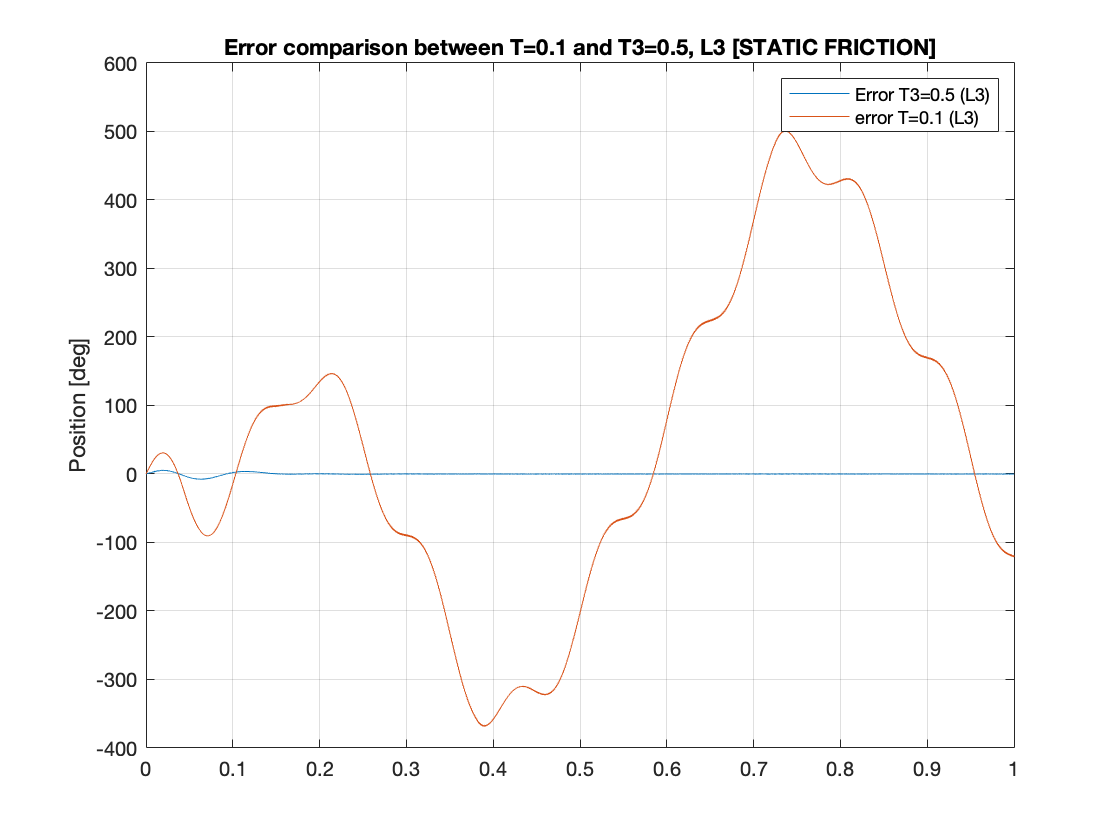

% DC motor + gearbox
set_param('SS_Error_space/DC motor + gearbox/static','Gain','est_par.tau_sf'); % Static friction
set_param('SS_Error_space/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction
% Run simulation
sim('SS_Extended_Est');

% Extract simulation results
ss_est.err_t = err.time; % time vector                        
ss_est.err_thl_nsf_w3 = err.signals(1).values(:,1); % load position (no static friction)
ss_est.err_thl_nsf_01 = err.signals(1).values(:,2); % load position (static friction)

% Plot simulation results
figure(22);
plot(ss_est.err_t, ss_est.err_thl_nsf_w3);
hold on;
plot(ss_est.err_t, ss_est.err_thl_nsf_01);
ylabel('Position [deg]');
grid on;
title('Error comparison between T=0.1 and T3=0.5, L3 [STATIC FRICTION]');
legend('Error T3=0.5 (L3)', 'error T=0.1 (L3)');

### 2.2.10 (Repeat point 2.2.8)

#### Simulation (Tracking of step with observer gain L3)

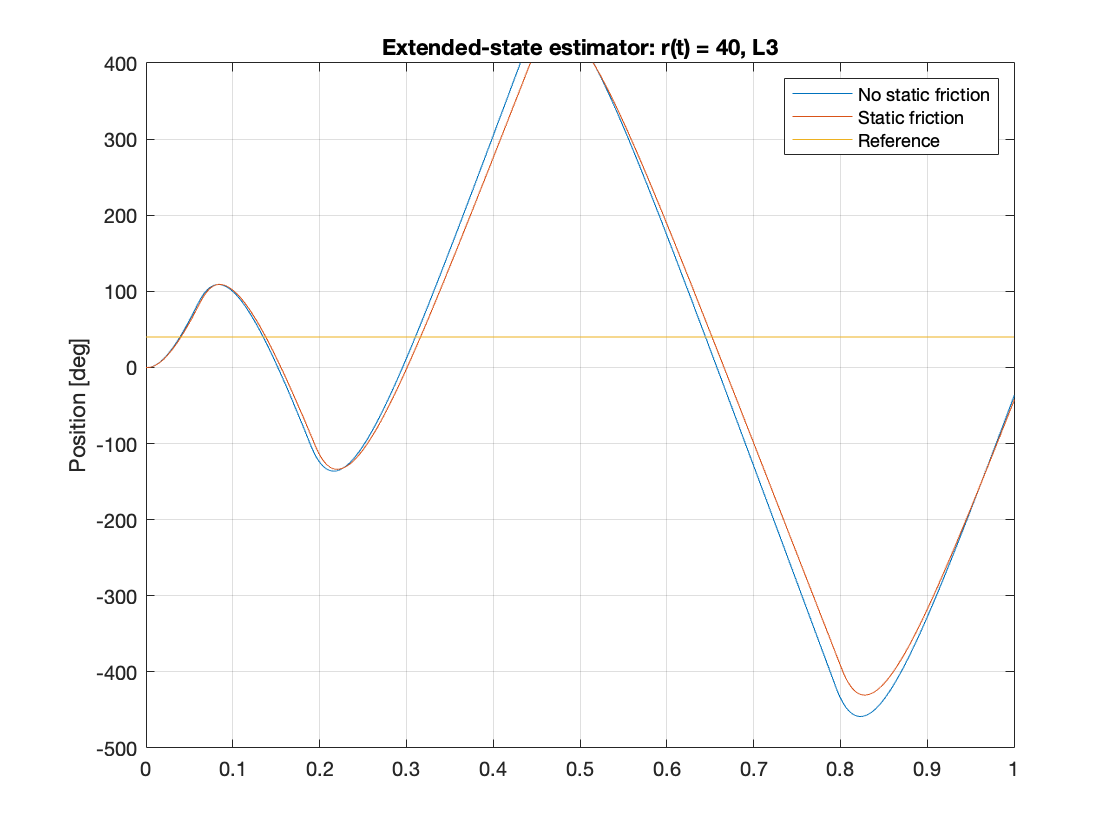

% Ref & Ref1 
set_param('SS_Extended_Est/switch','sw','0');
set_param('SS_Extended_Est/switch1','sw','0');
% DC motor + gearbox
set_param('SS_Error_space/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Error_space/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Extended_Est');

% Extract simulation results
ss_est.t = simres.time; % time vector                        
ss_est.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
ss_est.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
ss_est.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(23);
plot(ss_est.t, ss_est.thl_nsf);
hold on;
plot(ss_est.t, ss_est.thl_sf);
hold on;
plot(ss_est.t, ss_est.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([-500,400]);
title('Extended-state estimator: r(t) = 40, L3');
legend('No static friction', 'Static friction', 'Reference');

## BODE METHOD

function [kp, ki, kd] = BodMet(w_gc,ph_m,simp_model)
[mag_wgc, phm_wgc] = bode(simp_model.P,w_gc); % gain,phase of P(iw_gc)
deltaK = 1/mag_wgc; % DeltaK
deltaPhi = -180 + ph_m - phm_wgc; % DeltaPhi
kp = deltaK * cosd(deltaPhi); % K_p
T_d = (tand(deltaPhi) + sqrt(tand(deltaPhi)^2 + 1))/(2*w_gc); % T_d
T_i = 4*T_d; % T_i
ki = kp/T_i; % K_i
kd = kp*T_d; % K_d
end